***E1*****是专家1对故障模式的正规三角二型模糊语言分布评估矩阵；**

data =readtable("E1.xlsx");
E1 = table2array(data(:,1:21));

***E2*****是专家1对故障模式的正规三角二型模糊语言分布评估矩阵；**

data =readtable("E2.xlsx");
E2 = table2array(data(:,1:21));

***E3*****是专家1对故障模式的正规三角二型模糊语言分布评估矩阵；**

data =readtable("E3.xlsx");
E3 = table2array(data(:,1:21));

\omega**是专家们对风险因素的评估矩阵；**

data =readtable("RF.xlsx");
omega = table2array(data(:,1:21));

**每个专家的权重 \lambda     **

lambda=[0.36,0.33,0.31];

** Linguistic terms and their corresponding CTriIT2FS-LTs.**

data =readtable("CTriIT2FS-LDA.xlsx");
L2CTriI = table2array(data);

**参数\theta，在TODIM中计算优势度。**

theta=1;

##    **4.2 The steps of extended TODIM method for** **FMEA under ****CTriIT2F-LD****A information**

**Step 1：通过将CTRIT2F-LDA联合起来，根据FMEA团队中的每个跨职能成员，在所有风险因素下对每个故障模式进行评估。然后计算出CTRIT2F-LDA矩阵和危险因素权重的评价值。**

M = lambda(1).*E1+lambda(2).*E2+lambda(3).*E3;
omega_sub = lambda(1).*omega(1,:)+lambda(2).*omega(2,:)+lambda(3).*omega(3,:);

**Step 2: Calculate the subjective weight of risk factors.计算风险因素（O S D）的主观权重。**

Maximum=[0,0,0,0,0,0,1];
Minimum=[1,0,0,0,0,0,0];
KK=dis(Maximum,Minimum,L2CTriI);
omega_j_s=zeros(1,3);
for i=1:3
    omega_j_s(i)=dis(omega_sub(1,7*i-6:7*i),Minimum,L2CTriI)/KK;
end
omega_j_s=omega_j_s/sum(omega_j_s);

**Step 3: Calculate the objective weight of risk factors.计算风险因素（O S D）的客观权重。**

max_En=def(expectation(Maximum,L2CTriI));
min_En=def(expectation(Minimum,L2CTriI));
M_entropy=zeros(12,3);
for j=1:3
    k=1+(j-1)*7;
    for i =1:12
        m1=M(i,k:k+6);
        M_entropy(i,j)=entropy(m1,max_En,min_En,L2CTriI);
    end
end
fei_M = M_entropy;

Then, the elements of the FMEA CTriIT2F-LDA matrix are normalized by eq.(31)

k=max(M_entropy);
for i = 1:3
    M_entropy(:,i)=M_entropy(:,i)./k(i);
end
M_entropy;

As a result, the objective weight of the risk factor  *r*j  is derived by eq.(31)

AA=sum(M_entropy);
BB=sum(sum(M_entropy));
omega_j_o=(1-AA)/(3-BB);

**Step 4: Rank the failure modes by applying the TODIM approach;应用TODIM方法对故障模式进行排序**

主观权重与客观权重聚合：

omega_j=omega_j_o.*omega_j_s;
k=sum(omega_j);
omega_j=omega_j./k;

**Step 4.1. 计算相对权重**

omega_jr=omega_j./max(omega_j);

**Step 4.2. 计算相对优势度（距离）**

dominance=[];

for j = 1:3
    temp  =  zeros(12,12);
    for i = 1:12
        for k =1:12
            m_ij=M(i,1+(j-1)*7:7*j);
            m_kj=M(k,1+(j-1)*7:7*j);
            if M_entropy(i,j)>M_entropy(k,j)
                temp(i,k)=sqrt((omega_jr(j)*dis(m_ij,m_kj,L2CTriI))/sum(omega_jr));
            elseif M_entropy(i,j)<M_entropy(k,j)
                temp(i,k)=sqrt((sum(omega_jr)*dis(m_ij,m_kj,L2CTriI))/omega_jr(j))*(-1/theta);
            else
                temp(i,k)=0;
            end

        end
    end
    dominance=[dominance;temp];
end
dominance;

**Step 4.3. 计算全局优势度（距离）**

global_dominances=dominance(1:12,:)+dominance(13:24,:)+dominance(25:36,:);

 **Step 4.4. 归一化处理全局优势度（行求和）**

Result=sum(global_dominances,2);
pi_f_i=(Result-min(Result))/(max(Result)-min(Result));

 **Step 4.5. 排序**

[order,index]=sort(pi_f_i,'descend');

 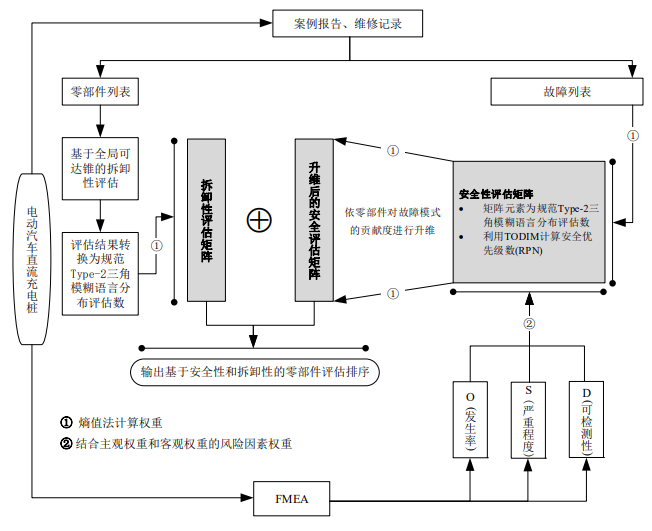

**Step 5. 读取零部件**$v_n$**引起故障**$f_i$**发生的概率，即**$k_{ni}$**，并计算安全性**$S_n$**。**

data =readtable("k_ni.xlsx");
k_ni = table2array(data(1:23,2:13));
S_n = zeros(1,23);
[n,j]=size(k_ni);
for  k= 1:n
    for l = 1:j
    S_n(1,k)=S_n(1,k) + sum(pi_f_i(l,1)*k_ni(k,l),"all");
    end
end
S_n = (S_n-min(S_n))/(max(S_n)-min(S_n));

**Step 6. 读取零部件的拆卸性**$D_n$**，并依权重**$\{\omega_s,\omega_d\}$**将**$S_n$**和**$D_n$**进行聚合。**

data =readtable("D_n.xlsx");
D_n = table2array(data(1:23,2));
D_n = (D_n-min(D_n))/(max(D_n)-min(D_n)); %归一化
pi_n = zeros(1,23);
omega_s = 0.5;
omega_d = 1-omega_s;
for i = 1:23
    pi_n(i)=S_n(i)*omega_s+D_n(i)*omega_d;
end

**Step 7. 依**$\pi(v_n)$** 将最终结果进行排序。**

[order_vn,index_vn]=sort(pi_n,'descend');

**结果处理：**$\{\omega_s,\omega_d\}$**对最终结果的影响**

result =readtable("result.xlsx");
result = table2array(result);

**绘图并保存**

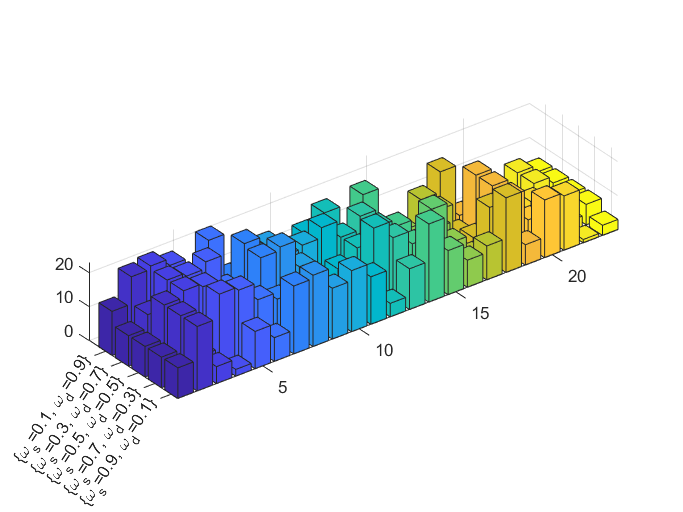


bar3(result);

yticklabels({'\{\omega_s=0.1, \omega_d=0.9\}','\{\omega_s=0.3, \omega_d=0.7\}','\{\omega_s=0.5, \omega_d=0.5\}','\{\omega_s=0.7, \omega_d=0.3\}','\{\omega_s=0.9, \omega_d=0.1\}'});
f=gcf;
exportgraphics(f,'AnnotatedPlot_0.tif');